# Projection on polytopes

clc
clear all
close all
rng(0)

# Data

A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
pinvA = pinv(A);
m     = size(A, 2);
N     = null(A, 'rational');
pinvN = pinv(N);
Ax = 7000;
Ay = 5000;
[ix_max, iy_max, is_max, ~, ~, ~] = max_values(Ax, Ay)

ix_max = 142.8571

iy_max = 200

is_max = 228.5714


function [ie, iz, is, ixy, iB] = generate_data
    A = [1  1  1  0  0  0  0  0  0;
         0  0  0  1  1  1  0  0  0;
         0  0  0  0  0  0  1  1  1;
        -1  0  0 -1  0  0 -1  0  0;
         0 -1  0  0 -1  0  0 -1  0;
         0  0 -1  0  0 -1  0  0 -1];
    pinvA = pinv(A);
    N     = null(A, 'rational');
    Ax = 7000;
    Ay = 5000;
    [ix_max, iy_max, ~, ~, ~, ~] = max_values(Ax, Ay);

    ie = 300*(2*rand(4, 1)-1);
    iz = N*ie;
    gx = rand * 2*pi;
    ixa = ix_max * sin(gx);
    ixb = ix_max * sin(gx-2*pi/3);
    ixc = ix_max * sin(gx+2*pi/3);
    gy = rand * 2*pi;
    iya = iy_max * sin(gy);
    iyb = iy_max * sin(gy-2*pi/3);
    iyc = iy_max * sin(gy+2*pi/3);
    ixy = [ixa; ixb; ixc; iya; iyb; iyc];
    iB = pinvA * ixy;
    is = iB + iz;
end

[ie, iz, is, ixy, iB] = generate_data

ie =   188.8342
  243.4752
 -223.8079
  248.0255


iz =   456.5270
   34.9737
 -491.5007
 -432.3094
  188.8342
  243.4752
  -24.2176
 -223.8079
  248.0255


is =   382.9873
   66.1828
 -554.7465
 -425.2793
  300.6131
  260.7991
  -72.7506
 -167.5921
  209.7864


ixy =  -105.5765
  136.1329
  -30.5563
  115.0426
 -199.2037
   84.1611


iB =   -73.5397
   31.2091
  -63.2459
    7.0301
  111.7788
   17.3239
  -48.5330
   56.2158
  -38.2391



original = struct();
original.ie = ie;
original.iz = iz;
original.is = is;
original.ixy = ixy;

function compare(original, optimal_projection, projection, name)
    disp(strcat(['Comparation of projection method: ', name]))
    disp('  Original | Optimal | Actual')
    disp('ie')
    disp([original.ie, optimal_projection.ie, projection.ie]);
    % disp('iz')
    % disp([original.iz, optimal_projection.iz, projection.iz]);
    disp('is')
    disp([original.is, optimal_projection.is, projection.is]);
    disp('ixy')
    disp([original.ixy, optimal_projection.ixy, projection.ixy]);
end

# Constraints


$$-\check{i_s}\leq i_B+N\cdot i_\varepsilon\leq\hat{i_s}$$


Define matrices


$$A_c\cdot i_\varepsilon\leq b_c$$


Ac = [N; -N];
bc = [is_max - iB; is_max + iB];
pinvAc = pinv(Ac);

Polytope properties

analyzePolytope(Ac, bc);


=== Polytope Properties ===
Dimensión afín   : 4
Acotado          : Sí
Número de facetas: 18
Número de vértices: 64
Número de aristas : 421
Volumen/Área     : N/A para dimensión >3
Centroide        : [ -14.83 7.426 5.291 -2.15 ]
ChebyCenter      : [ 4.218 45.07 59.78 -38.95 ]
Inradius         : 112.6
Diámetro         : 914.3



Visualize slice

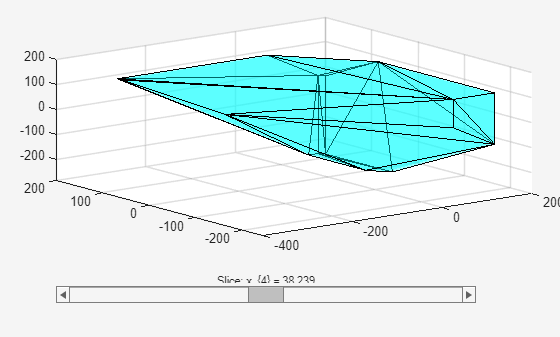

freeDim = 4;
visualizeSlice3D(Ac, bc, freeDim);

## Active set solver

H   = eye(4);
f   = -ie;
options = mpcActiveSetOptions;
[ie_proj, exitflag, iA, lambda] = mpcActiveSetSolver(H, f, Ac, bc, zeros(0, 4), zeros(0, 1), false(18, 1), options);
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

exitflag

exitflag = int32
3


optimal_projection = struct();
optimal_projection.ie = ie_proj;
optimal_projection.iz = iz_proj;
optimal_projection.is = is_proj;
optimal_projection.ixy = ixy_proj;

% Max constraint violation original ie
max(Ac*ie - bc)

ans = 326.1751

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Hardnet-aff

ie_correction = pinvAc * max(0, Ac * ie - bc);
ie_proj = ie - ie_correction;
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'HardNet-Aff')

Comparation of projection method: HardNet-Aff
  Original | Optimal | Actual
ie
  188.8342  116.7926  164.0916
  243.4752   80.3876  177.6413
 -223.8079 -223.8079 -197.1233
  248.0255   84.9380  213.7119
is
  382.9873  -15.2295  284.7818
   66.1828  138.2244   64.2408
 -554.7465 -228.5714 -454.5991
 -425.2793 -190.1501 -334.7028
  300.6131  228.5714  275.8704
  260.7991   97.7115  194.9652
  -72.7506   90.3370  -65.1216
 -167.5921 -167.5921 -140.9075
  209.7864   46.6988  175.4728
ixy
 -105.5765 -105.5765 -105.5765
  136.1329  136.1329  136.1329
  -30.5563  -30.5563  -30.5563
  115.0426  115.0426  115.0426
 -199.2037 -199.2037 -199.2037
   84.1611   84.1611   84.1611



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 326.1751

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 226.0277

## Scalar clipping

Ac_ie = Ac * ie;
alpha_i = inf(size(Ac_ie));
pos = Ac_ie > 0;            
alpha_i(pos) = bc(pos) ./ Ac_ie(pos);
alpha = min(1, min(alpha_i));
ie_proj = alpha * ie;
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Scalar Clipping')

Comparation of projection method: Scalar Clipping
  Original | Optimal | Actual
ie
  188.8342  116.7926   63.5180
  243.4752   80.3876   81.8975
 -223.8079 -223.8079  -75.2820
  248.0255   84.9380   83.4281
is
  382.9873  -15.2295   80.0218
   66.1828  138.2244   42.9731
 -554.7465 -228.5714 -228.5714
 -425.2793 -190.1501 -138.3854
  300.6131  228.5714  175.2968
  260.7991   97.7115   99.2214
  -72.7506   90.3370  -56.6790
 -167.5921 -167.5921  -19.0662
  209.7864   46.6988   45.1889
ixy
 -105.5765 -105.5765 -105.5765
  136.1329  136.1329  136.1329
  -30.5563  -30.5563  -30.5563
  115.0426  115.0426  115.0426
 -199.2037 -199.2037 -199.2037
   84.1611   84.1611   84.1611



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 326.1751

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 2.8422e-14

## Cimmino original

Mean of constraint violations

K      = 5;         % Number of iterations
lambda = 1.5;         % Relaxation factor
ie_proj = ie;       % Initialize projection
tic
n2 = sum(Ac.^2, 2); % Precalculate squared norm of each row of Ac
for k = 1:K
    R = Ac * ie_proj - bc;
    V = max(R, 0) ./ n2;
    d = (Ac.' * V) / size(Ac, 1);
    ie_proj = ie_proj - lambda * d;
end
toc

Elapsed time is 0.004764 seconds.


iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Cimmino Mean')

Comparation of projection method: Cimmino Mean
  Original | Optimal | Actual
ie
  188.8342  116.7926  137.5163
  243.4752   80.3876  154.9265
 -223.8079 -223.8079 -229.8057
  248.0255   84.9380  188.9343
is
  382.9873  -15.2295  178.0316
   66.1828  138.2244  123.4985
 -554.7465 -228.5714 -407.1067
 -425.2793 -190.1501 -285.4127
  300.6131  228.5714  249.2951
  260.7991   97.7115  172.2504
  -72.7506   90.3370   -7.6615
 -167.5921 -167.5921 -173.5899
  209.7864   46.6988  150.6951
ixy
 -105.5765 -105.5765 -105.5765
  136.1329  136.1329  136.1329
  -30.5563  -30.5563  -30.5563
  115.0426  115.0426  115.0426
 -199.2037 -199.2037 -199.2037
   84.1611   84.1611   84.1611



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 326.1751

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 178.5352

## Cimmino modified

Max of constraint violations

K      = 2;         % Number of iterations
lambda = 1;         % Relaxation factor
ie_proj = ie;       % Initialize projection
tic
for k = 1:K
    R = Ac * ie_proj - bc;
    V = max(R, 0);
    [vmax, idx_max] = max(V);
    if vmax<=0
        break;
    end
    ai    = Ac(idx_max, :)';
    ri    = ai' * ie_proj - bc(idx_max);
    corr  = (ri / (ai' * ai)) * ai;
    ie_proj = ie_proj - lambda * corr;
end
toc

Elapsed time is 0.002494 seconds.


iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Cimmino Max')

Comparation of projection method: Cimmino Max
  Original | Optimal | Actual
ie
  188.8342  116.7926  116.7926
  243.4752   80.3876   80.3876
 -223.8079 -223.8079 -223.8079
  248.0255   84.9380   84.9380
is
  382.9873  -15.2295  -15.2295
   66.1828  138.2244  138.2244
 -554.7465 -228.5714 -228.5714
 -425.2793 -190.1501 -190.1501
  300.6131  228.5714  228.5714
  260.7991   97.7115   97.7115
  -72.7506   90.3370   90.3370
 -167.5921 -167.5921 -167.5921
  209.7864   46.6988   46.6988
ixy
 -105.5765 -105.5765 -105.5765
  136.1329  136.1329  136.1329
  -30.5563  -30.5563  -30.5563
  115.0426  115.0426  115.0426
 -199.2037 -199.2037 -199.2037
   84.1611   84.1611   84.1611



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 326.1751

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Dykstra

K        = 1;         % Número de iteraciones externas
lambda   = 1;         % Factor de relajación (p.ej. 1.2)
ie_proj  = ie;        % Inicializa la proyección
n2       = sum(Ac.^2, 2);    % Precalcula ||a_i||^2 para cada restricción
p        = zeros(size(Ac));  % Correcciones acumuladas, una fila por restricción

tic
for k = 1:K
    % Recorremos cada semiespacio i=1..m
    for i = 1:size(Ac,1)
        ai  = Ac(i,:).';
        bi  = bc(i);
        aux = ie_proj + p(i,:).';
        ri  = ai.'*aux - bi;
        if ri > 0
            corr   = (ri/n2(i)) * ai;
            x_new  = aux - lambda * corr;
        else
            x_new  = aux;
        end
        p(i,:)    = (aux - x_new).';
        ie_proj   = x_new;
    end
end
toc

Elapsed time is 0.004907 seconds.



iz_proj   = N * ie_proj;
is_proj   = iB + iz_proj;
ixy_proj  = A * is_proj;

projection = struct();
projection.ie   = ie_proj;
projection.iz   = iz_proj;
projection.is   = is_proj;
projection.ixy  = ixy_proj;

compare(original, optimal_projection, projection, 'Dykstra')

Comparation of projection method: Dykstra
  Original | Optimal | Actual
ie
  188.8342  116.7926  116.7926
  243.4752   80.3876   80.3876
 -223.8079 -223.8079 -262.4119
  248.0255   84.9380   84.9380
is
  382.9873  -15.2295  -53.8334
   66.1828  138.2244  176.8284
 -554.7465 -228.5714 -228.5714
 -425.2793 -190.1501 -190.1501
  300.6131  228.5714  228.5714
  260.7991   97.7115   97.7115
  -72.7506   90.3370  128.9409
 -167.5921 -167.5921 -206.1961
  209.7864   46.6988   46.6988
ixy
 -105.5765 -105.5765 -105.5765
  136.1329  136.1329  136.1329
  -30.5563  -30.5563  -30.5563
  115.0426  115.0426  115.0426
 -199.2037 -199.2037 -199.2037
   84.1611   84.1611   84.1611



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 326.1751

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Douglas Peaceman Rachford

K = 2;
lambda = 1;               % relajación (normalmente 1)
x = ie;                   % estado
m = size(Ac,1);

tic
for k = 1:K
    x_old = x;
    % reflejar sucesivamente por cada semiespacio
    for i = 1:m
        ai = Ac(i,:).'; bi = bc(i);
        % proyección ortogonal a semiespacio i
        ri = ai.'*x - bi;
        if ri > 0
            p = x - (ri/(ai.'*ai)) * ai;
        else
            p = x;
        end
        % reflexión
        r = 2*p - x;
        % relajación
        x = x + lambda*(r - x);
    end
    % opcional: media con x_old para estabilidad DR
    x = 0.5*(x + x_old);
end
toc

Elapsed time is 0.005074 seconds.



ie_proj = x;
iz_proj   = N * ie_proj;
is_proj   = iB + iz_proj;
ixy_proj  = A * is_proj;

projection = struct();
projection.ie   = ie_proj;
projection.iz   = iz_proj;
projection.is   = is_proj;
projection.ixy  = ixy_proj;

compare(original, optimal_projection, projection, 'Douglas Peaceman Rachford')

Comparation of projection method: Douglas Peaceman Rachford
  Original | Optimal | Actual
ie
  188.8342  116.7926  116.7926
  243.4752   80.3876   80.3876
 -223.8079 -223.8079 -246.1833
  248.0255   84.9380   84.9380
is
  382.9873  -15.2295  -37.6048
   66.1828  138.2244  160.5997
 -554.7465 -228.5714 -228.5714
 -425.2793 -190.1501 -190.1501
  300.6131  228.5714  228.5714
  260.7991   97.7115   97.7115
  -72.7506   90.3370  112.7123
 -167.5921 -167.5921 -189.9675
  209.7864   46.6988   46.6988
ixy
 -105.5765 -105.5765 -105.5765
  136.1329  136.1329  136.1329
  -30.5563  -30.5563  -30.5563
  115.0426  115.0426  115.0426
 -199.2037 -199.2037 -199.2037
   84.1611   84.1611   84.1611



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 326.1751

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0